## Очищення середовища

clear, close all

## 1.Завантаження тестових зображень

Завантажуємо кілька тестових зображень з бібліотеки MATLAB

pout = imread('pout.tif');
cameraman = imread('cameraman.tif');
peppers = imread('peppers.png');

## 2.Відображення вихідних зображень

Відображення зображень для перевірки

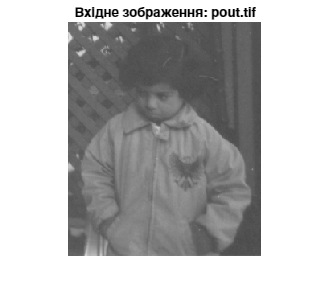

figure, imshow(pout), title('Вхідне зображення: pout.tif');

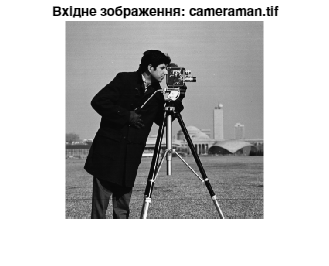

figure, imshow(cameraman), title('Вхідне зображення: cameraman.tif');

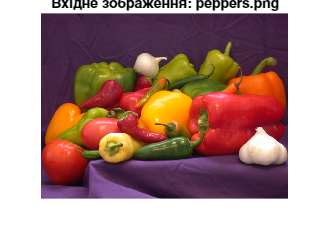

figure, imshow(peppers), title('Вхідне зображення: peppers.png');

## 3.Зашумлення зображень

Зашумлюємо зображення нормальним білим шумом і імпульсною перешкодою (salt & pepper noise)

pout_noise = imnoise(pout, 'gaussian', 0, 0.02);  % Нормальний білий шум
cameraman_noise = imnoise(cameraman, 'salt & pepper', 0.02);  % Імпульсна перешкода
peppers_noise = imnoise(peppers, 'salt & pepper', 0.05);  % Імпульсна перешкода з більшою щільністю

## 4.Відображення зашумлених зображень

disp('Зашумлені зображення:');

Зашумлені зображення:


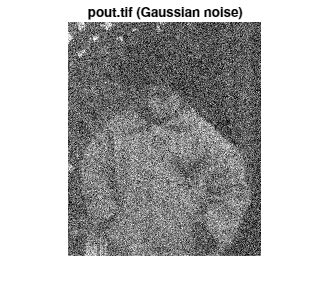

figure, imshow(pout_noise), title('pout.tif (Gaussian noise)');

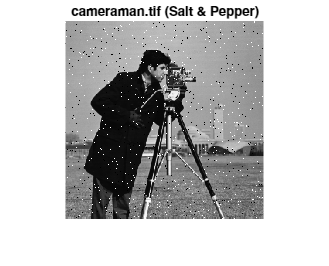

figure, imshow(cameraman_noise), title('cameraman.tif (Salt & Pepper)');

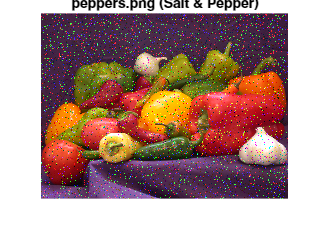

figure, imshow(peppers_noise), title('peppers.png (Salt & Pepper)');

## 5.Лінійна фільтрація з використанням віконних фільтрів

Фільтрація з використанням низькочастотного фільтра (середнє фільтрування)

h_low = fspecial('average', [3 3]);  % 3x3 середнє фільтрування
pout_low = imfilter(pout, h_low);
cameraman_low = imfilter(cameraman, h_low);
peppers_low = imfilter(peppers, h_low);

 Фільтрація з використанням високочастотного фільтра (високочастотне підсилення)

h_high = fspecial('laplacian', 0.2);  % Лапласів оператор для високих частот
pout_high = imfilter(pout, h_high);
cameraman_high = imfilter(cameraman, h_high);
peppers_high = imfilter(peppers, h_high);

## 6.Відображення результатів фільтрації

disp('Фільтрація низьких частот:');

Фільтрація низьких частот:


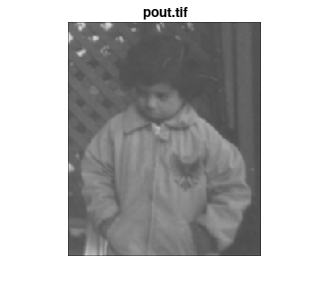

figure, imshow(pout_low), title('pout.tif');

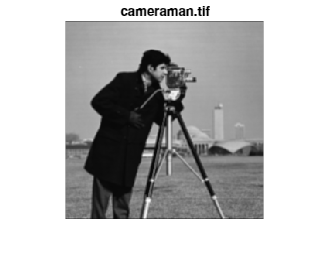

figure, imshow(cameraman_low), title('cameraman.tif');

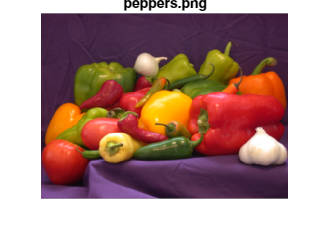

figure, imshow(peppers_low), title('peppers.png');


disp('Фільтрація високих частот:');

Фільтрація високих частот:


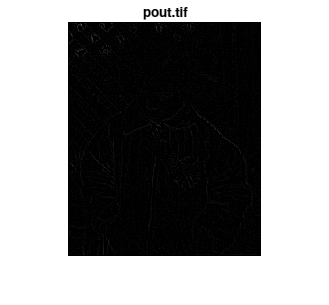

figure, imshow(pout_high), title('pout.tif');

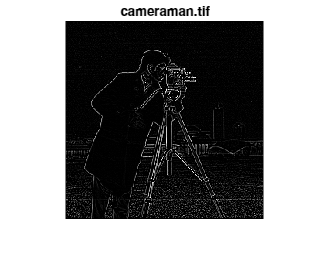

figure, imshow(cameraman_high), title('cameraman.tif');

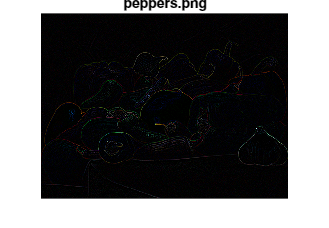

figure, imshow(peppers_high), title('peppers.png');

## 7.Фільтрація зашумлених зображень

Фільтрація зашумлених зображень низькочастотними та високочастотними фільтрами

pout_noise_low = imfilter(pout_noise, h_low);
cameraman_noise_low = imfilter(cameraman_noise, h_low);
peppers_noise_low = imfilter(peppers_noise, h_low);

pout_noise_high = imfilter(pout_noise, h_high);
cameraman_noise_high = imfilter(cameraman_noise, h_high);
peppers_noise_high = imfilter(peppers_noise, h_high);

## Відображення результатів фільтрації зашумлених зображень

disp('Зашумлені зображення після низькочастотної фільтрації:');

Зашумлені зображення після низькочастотної фільтрації:


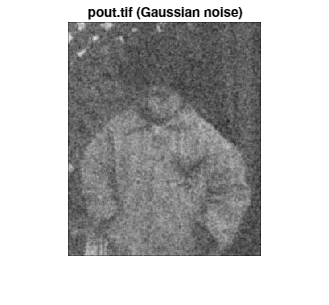

figure, imshow(pout_noise_low), title('pout.tif (Gaussian noise)');

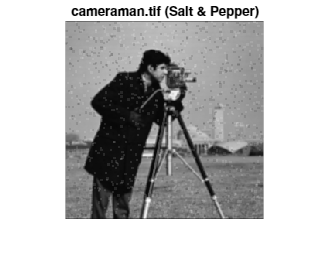

figure, imshow(cameraman_noise_low), title('cameraman.tif (Salt & Pepper)');

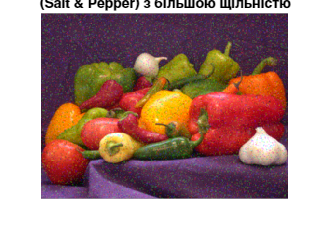

figure, imshow(peppers_noise_low), title(sprintf('peppers.png\n(Salt & Pepper) з більшою щільністю'));


disp('Зашумлене зображення після високочастотної фільтрації');

Зашумлене зображення після високочастотної фільтрації


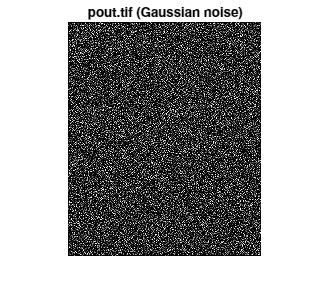

figure, imshow(pout_noise_high), title('pout.tif (Gaussian noise)');

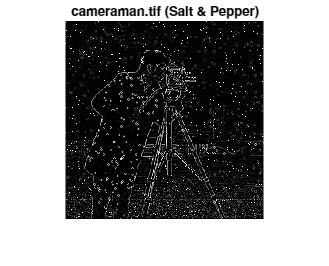

figure, imshow(cameraman_noise_high), title('cameraman.tif (Salt & Pepper)');

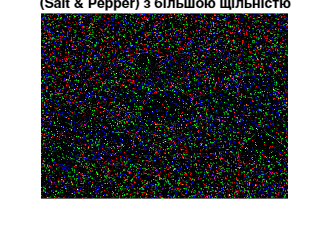

figure, imshow(peppers_noise_high), title(sprintf('peppers.png\n(Salt & Pepper) з більшою щільністю'));

## 8.Адаптивна фільтрація Вінера

Застосовуємо адаптивний фільтр Вінера для відновлення зашумлених зображень

pout_wiener = wiener2(pout_noise, [5 5]);
cameraman_wiener = wiener2(cameraman_noise, [5 5]);

R = peppers_noise(:,:,1);
G = peppers_noise(:,:,2);
B = peppers_noise(:,:,3);

R_wiener = wiener2(R, [5 5]);
G_wiener = wiener2(G, [5 5]);
B_wiener = wiener2(B, [5 5]);

peppers_wiener = cat(3, R_wiener, G_wiener, B_wiener);

## Відображення результатів фільтрації Вінером

disp('Зображення після адаптивної фільтрації Вінера ');

Зображення після адаптивної фільтрації Вінера 


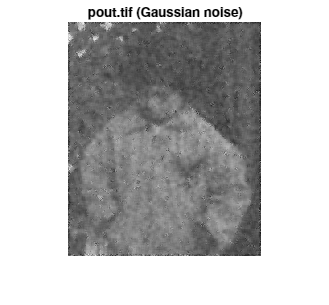

figure, imshow(pout_wiener), title('pout.tif (Gaussian noise)');

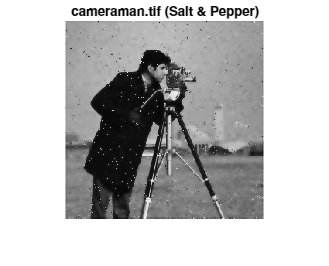

figure, imshow(cameraman_wiener), title('cameraman.tif (Salt & Pepper)');

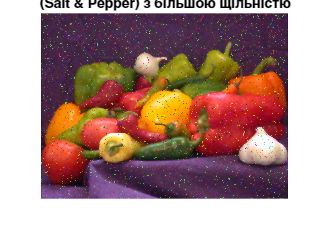

figure, imshow(peppers_wiener), title(sprintf('peppers.png\n(Salt & Pepper) з більшою щільністю'));

## 9.Медіанна фільтрація

Застосовуємо медіанну фільтрацію для зашумлених зображень

pout_median = medfilt2(pout_noise, [3 3]);
cameraman_median = medfilt2(cameraman_noise, [3 3]);

R_medfilt = medfilt2(R, [3 3]);
G_medfilt = medfilt2(G, [3 3]);
B_medfilt = medfilt2(B, [3 3]);

peppers_median = cat(3, R_medfilt, G_medfilt, B_medfilt);

## Відображення результатів медіанної фільтрації

disp('Зображення після медіанної фільтрації  ');

Зображення після медіанної фільтрації  


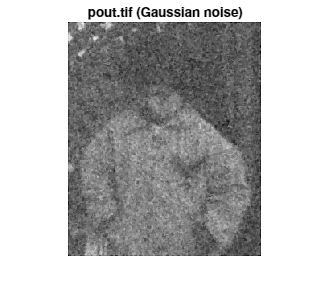

figure, imshow(pout_median), title('pout.tif (Gaussian noise)');

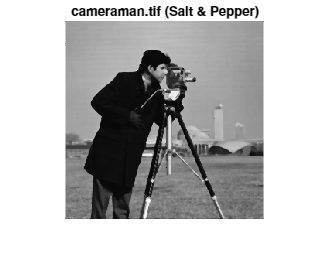

figure, imshow(cameraman_median), title('cameraman.tif (Salt & Pepper)');

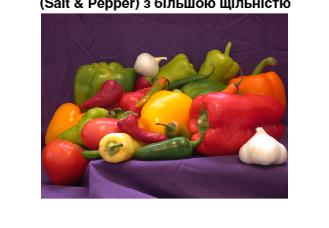

figure, imshow(peppers_median), title(sprintf('peppers.png\n(Salt & Pepper) з більшою щільністю'));

# 10. Контрольні запитання

### 1. Поясніть процедуру лінійної фільтрації зображення віконним фільтром:

Лінійна фільтрація зображення віконним фільтром полягає в заміні значення

кожного пікселя на певну функцію значень пікселів в його околиці (наприклад,

середнє або медіану). Це дозволяє зменшити вплив шуму на зображення. Віконний

фільтр визначає, яку частину пікселів брати для обчислення нового значення.

Зазвичай використовуються фільтри середнього або гаусового типу.

### 2. Чому відрізняються "вікна фільтрів" для низькочастотної і високочастотної фільтрації:

Вікна фільтрів для низькочастотної фільтрації зазвичай більші та "м'якші",

оскільки вони мають на меті згладити зображення та усунути високочастотний

шум. Для високочастотної фільтрації використовуються малі фільтри, щоб

виділити деталі, контрасти та риси зображення, оскільки ці фільтри посилюють

високочастотні компоненти.

### 3. Як змінюється вигляд зображення після його фільтрації низькочастотними фільтрами:

Після фільтрації низькочастотними фільтрами зображення стає більш згладженим,

з розмитими контрастами та менш вираженими деталями. Шум зменшується, але

також можуть згладжуватись різкі межі між об'єктами.

###  4. Як змінюється вигляд зображення після його фільтрації високочастотними фільтрами:

Після фільтрації високочастотними фільтрами зображення стає більш різким

і контрастним. Високочастотні фільтри виділяють дрібні деталі, контури

і змінюють яскравість різких меж між об'єктами, але при цьому можуть

підсилювати шум.

### 5. Для перешкод якого характеру більше підходить медіанна фільтрація, і чому?

Медіанна фільтрація найбільше підходить для зменшення імпульсних перешкод,

таких як "сіль і перець", оскільки вона замінює екстремальні пікселі (які

можуть бути шумом) на середнє значення їхнього околу. Це дозволяє зберегти

основну структуру зображення, видаляючи тільки випадкові екстремальні пікселі.